# Cinemática Servos

## **Cinemática inversa para el manipulador**

Se tiene un manipulador como el de la figura.

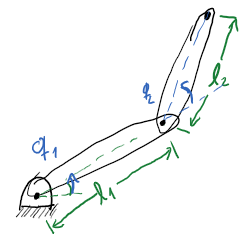

Parámetros delmanipulador

Se busca obtener los $q_1$ y $q_2$ de forma que el extremo distal del manipulador llegue a x,y. Se observa que el manipulador puede posicionarse de dos formas: codo arriba y codo abajo y se pueden representar de la siguiente forma: 

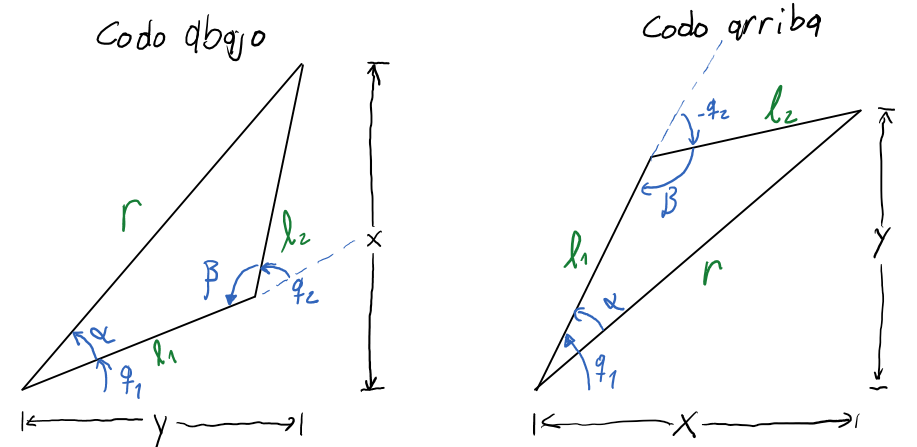

Para ambos casos, por teorema del coseno:


$$\alpha =\textrm{acos}\left(\frac{l_1^2 +r^2 -l_2^2 }{2\;l_1 \;r}\right)$$


y por el teorema del seno: 


$$\beta =\textrm{asin}\left(\frac{r}{l_2 }\sin \left(\alpha \right)\right)$$


### Codo Abajo:


$$\textrm{atan}\left(y,x\right)=q_1 +\alpha \;$$



$$q_1 =\textrm{atan}\left(y,x\right)-\alpha$$


y


$$\pi =q_2 +\beta$$



$$q_2 =\pi -\beta$$


### Codo Arriba:


$$q_1 =\textrm{atan}\left(y,x\right)+\alpha$$


y


$$\pi =-q_2 +\beta$$



$$q_2 =\beta -\pi$$


## Obtención de la figura de trébol estilizado:

Se obtuvo de forma empírica la siguiente ecuación para un trébol estilizado de tres hojas que esté inscrito en un cuadrado concéntrico de lado 1:

## 
$$\rho =\frac{5+2*\mathrm{cos}\left(3\left(\theta -\gamma \right)\right)}{7}$$


En donde $\gamma$ es la rotación del trébol.

Se calculan los valores x, y para el trébol y se grafica:

clear all, clc, close all
res = 10000;
theta = linspace(2*pi/res,2*pi,res);
gamma = 0;
rho = (5+2*cos(3*(theta-gamma)))/7;
[x_pos y_pos] = pol2cart(theta,rho);
lenghts=sqrt((x_pos+2).*(x_pos+2)+(y_pos+2).*(y_pos+2))

lenghts =     3.6059    3.6062    3.6066    3.6069    3.6073    3.6076    3.6080    3.6083    3.6086    3.6090    3.6093    3.6097    3.6100    3.6103    3.6107    3.6110    3.6113    3.6116    3.6120    3.6123    3.6126    3.6130    3.6133    3.6136    3.6139    3.6142    3.6146    3.6149    3.6152    3.6155    3.6158    3.6161    3.6165    3.6168    3.6171    3.6174    3.6177    3.6180    3.6183    3.6186    3.6189    3.6192    3.6195    3.6198    3.6201    3.6204    3.6207    3.6210    3.6213    3.6216


maxLenght=max(abs(lenghts))

maxLenght = 3.6584

L1=maxLenght-2

L1 = 1.6584

L2=maxLenght-L1

L2 = 2



fun=@angArm

fun = function_handle with value:
    @angArm


x0=[0,0];
x=fsolve(fun,x0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x = 	1.0e+-4 *

    0.7016   -0.4325


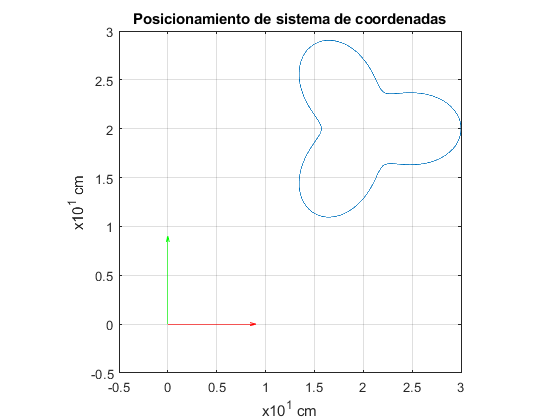

plot(x_pos+2,y_pos+2)
hold on
pbaspect([1 1 1])
grid on 
quiver(0,0,1,0,'r');
quiver(0,0,0,1,'g');
title('Posicionamiento de sistema de coordenadas')
xlabel('x10^1 cm') 
ylabel('x10^1 cm') 

function F=angArm(x,x_pos,y_pos) 
    F(1)=-0.5+1.2447*cos(x(1))+2*cos(x(1)-x(2));
    F(1)=-3.1416e-04 +1.2447*sin(x(1))+2*sin(x(1)-x(2));
end
